## Levenberg-Marquardt

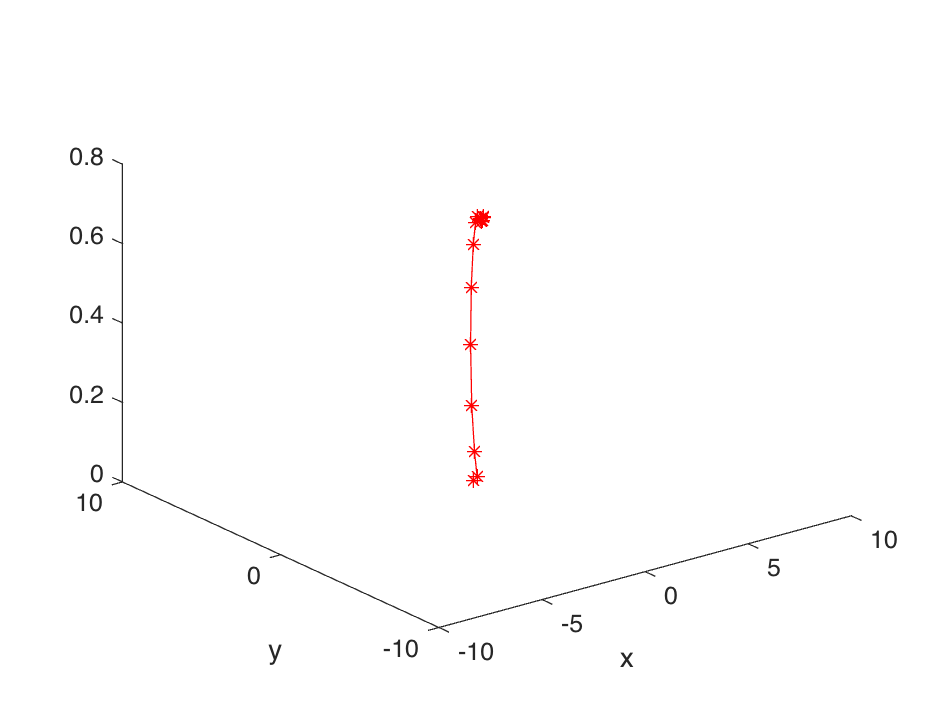

clc;close all;clear all;

q_0 = [0; 0; 0; 0; 0; 0];


thresh=1e-5;
max_iter=10000;

th = pi/2;
disp = [0.2; 0.5; 0.7];
rot = [cos(th) -sin(th) 0;
       sin(th) cos(th)  0;
       0         0      1];

Tbe = [rot, disp; 0 0 0 1];

[q_des, iter] = LM_method(Tbe, q_0);

fk(q_des)

ans =    -0.0000   -1.0000    0.0000    0.2000
    1.0000   -0.0000    0.0000    0.4999
   -0.0000    0.0000    1.0000    0.6999
         0         0         0    1.0000


Tbe

Tbe =     0.0000   -1.0000         0    0.2000
    1.0000    0.0000         0    0.5000
         0         0    1.0000    0.7000
         0         0         0    1.0000
